# `Complicated Duggoff Tire model`

`Simulink`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Autonomy in Vehicles ECE 5553  | Ohio State University | 2/20/2023`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents `

`1. Introduction `

`2. The Dugoff tire force model`

`    a) Free Body Diagram`

`    b) Wheel slip background`

`    c) Block Diagram`

`    d) Model Parameters`

`    e) Tire forces vs slip ratio (sim)`

`    f) Tire forces vs side slip angle (sim)`

`    g) tire force ellipse, relating Fx and Fy`

`3. Conclusions and future work`

# `Introduction `

`    This report contains tire modeling work formatted as a markdown file. Code, written in MATLAB, is contained in this file to run SIMULINK models, which must be downloaded separtely, if contained in the correctly named folder in the workspace path, no changes are necessary to repeat the same results. This report includes projects from the following Ohio State University courses: Vehicle Systems and Control Mechanical Engineering (ME) 8352 and Autonomy in Vehicles Electical and Computer Engineering (ECE) 5553 offered and completed by Brian Lesko in Autumn 2022 and Spring 2023 respectively in person at Ohio State's Columbus Campus. Topics covered in this report are partly inspired by these courses as well as the book Robust Controls of Mechatronic Systems by Dr. Levent Guvenc. `

`    The report covers the Duggoff Tire model. The Dugoff tire model is a well-known vehicle tire model used in the field of vehicle dynamics and control. It was first introduced in a paper titled "An analysis of tire traction properties and their influence on vehicle dynamic performance" by Dr. Hans Dugoff in 1965. The Dugoff tire model is typically used to simulate the longitudinal forces (i.e., forces acting parallel to the vehicle's direction of travel) generated by a tire on a road surface. This includes forces due to tire slip, which occurs when the tire's rotation speed is different from the vehicle's velocity. The model is often used in simulations of vehicle dynamics and control, such as for studying the effects of different tire properties on vehicle handling and performance.One recent paper that uses the Dugoff tire model is "A novel control approach for vehicle autonomous emergency braking based on tire-road friction estimation" by X. Chen et al. (2021). In this paper, the authors use the Dugoff tire model to estimate the tire-road friction coefficient, which is used in a control algorithm for autonomous emergency braking.`

`    There are a few assumptions made by the Dugoff tire model, one of the main ones is that the tire contact patch can be modeled as a rectangular area. This is a simplification since the contact patch is actually a complex, curved shape. The model also assumes that the tire's lateral force is proportional to its slip angle (i.e., the angle between the tire's direction of travel and its direction of rotation), which may not hold true at larger slip angles. The model used here is a Complicated Duggoff Tire Model. `

`    Overall, the Dugoff tire model provides a simple and efficient way to model tire forces in vehicle simulations. It is also relatively easy to implement compared to more complex tire models. However, a weakness is that it may not capture some of the more intricate tire behavior, such as transient effects during cornering. Additionally, the model may not work well for extreme driving conditions or for certain tire types, such as those with very stiff sidewalls.`

# `Free Body Diagram`

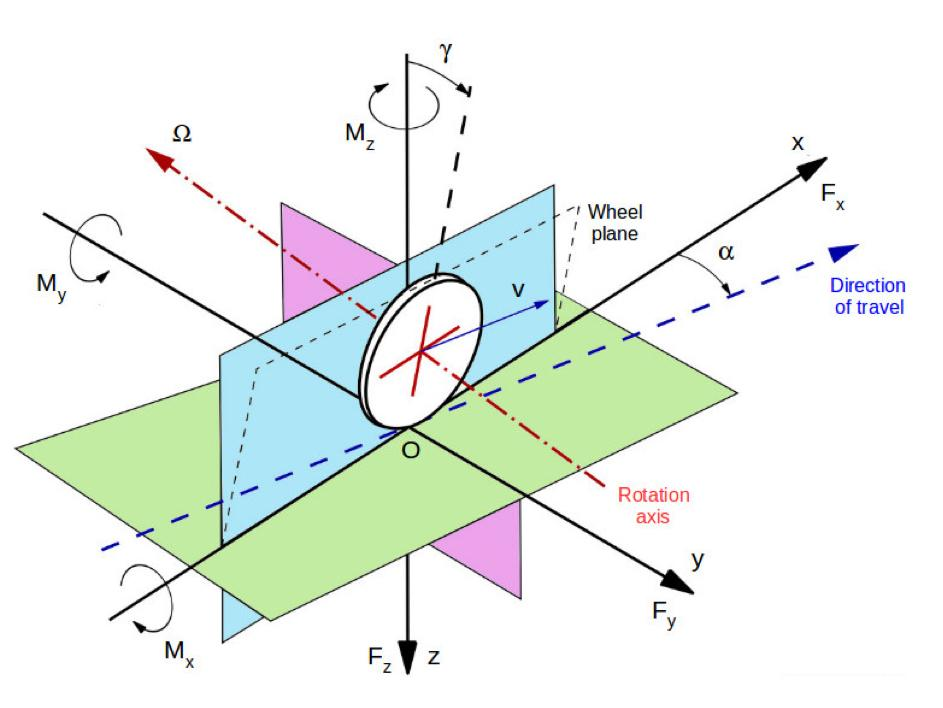

# Wheel Slip

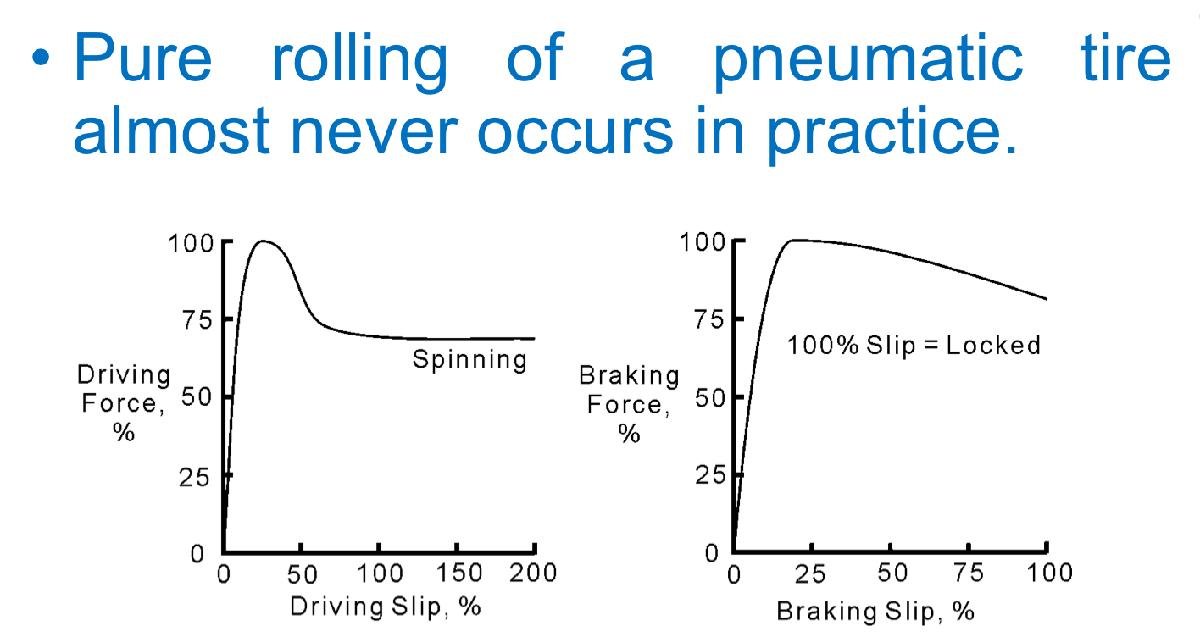

# Block Diagram 

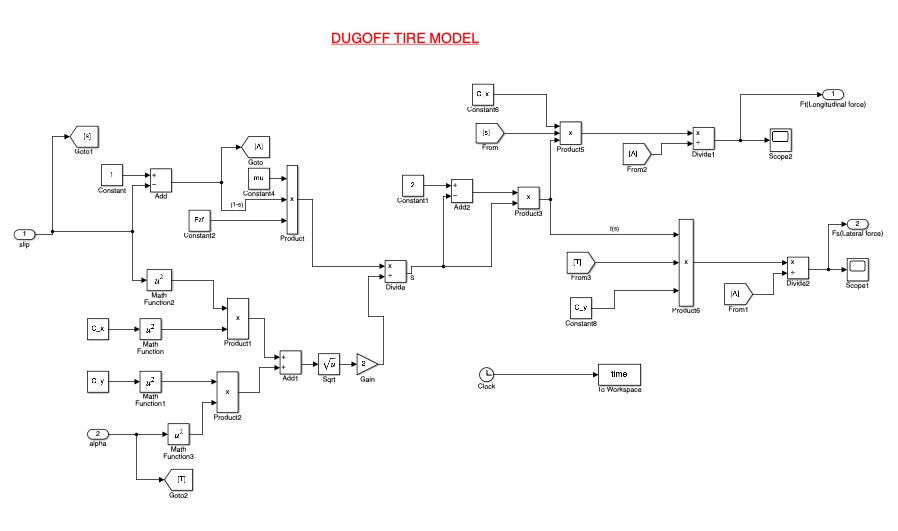

# Model Parameters

clc; clear; close all

[M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters();
%function [M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters()
%    %Parameters
%     warning off
%     M=2000*9.81;          % Mass of the vehicle[N]
%     eta_t=0.9;            %Transmission Efficiency	
%     lambda_t=1.0;         %Gear Ratio	
%     lambda_f=4.1;         %Final Drive Ratio	
%     I_w=1;                %Inertia of the Wheel[kgm2]
%     R_w=0.3;              %Wheel Radius[m]
%     Meq=0.1*M;            %Equivalent Mass Factor	
%     C_d=0.29;             %Drag coefficient 	
%     rho=1.225;            %Air density[kg/m3]
%     A_f=2.8;              %Frontal area	[m2]
%     g=9.81;               % [N/m2]
%     C_rr=0.015;           %Rolling resistance coefficient	
%     C_x=3e5;              %Longitudinal Stiffness[N]
%     L=2.85;               %Wheelbase[m]
%     l_f=1.3;              %Distance from the center of gravity of the vehicle (CG) to the front axle [m]
%     l_r=1.55;             %Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
%     C_y=1.5e5;            %Cornering Stiffness of Front and Rear Tires [N/rad]
%     I_z=3700;             %Inertia moment around z axis J or Iz [kg/m2]
%     mu=0.7;               % Road friction coefficient
%     Fzf=(l_r*M)/(2*L);    % Vertical force for front tire
%     Fzr=(l_f*M)/(2*L);    % Vertical force for rear tire
%end 

# `Tire forces vs slip ratio (sim)`

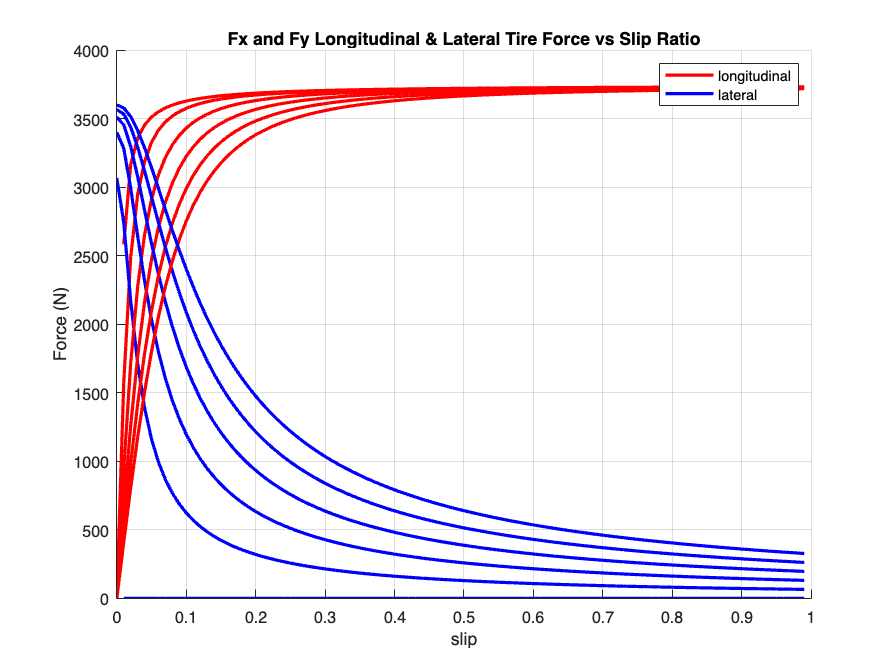

s=[0:0.01:1]';
figure, hold on
for alpha = (0:2:10)*pi/180
    %at = [a*ones(length(time))',time];
    sim('Duggoff_Tire_Model');
    %v1 = saveVehicle(Fx,Fy,s,a); plot(v1.Fx,v1.s); 
    plot(s,Fx,'r','linewidth',2)
    plot(s,Fy,'b','linewidth',2)
end 
xlabel('slip'),ylabel('Force (N)'), title('Fx and Fy Longitudinal & Lateral Tire Force vs Slip Ratio'), grid on
legend('longitudinal','lateral')

The vehicle can either turn or brake quickly. Doing both simultaneously requires wheel slip control and results in a fraction of the performance for turning and braking. 

# `Tire forces vs side slip angle (sim)`

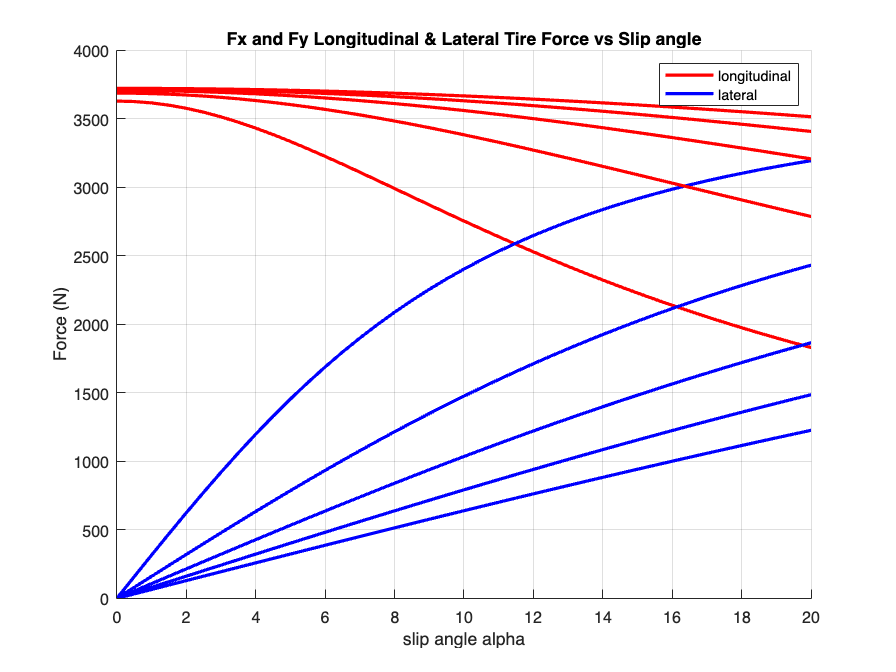

close all
alpha=[0:.5:20]'*pi/180;
figure, hold on
for s = (0.1:.1:0.5)
    sim('Duggoff_Tire_Model');
    plot(alpha*180/pi,Fx,'r','linewidth',2)
    plot(alpha*180/pi,Fy,'b','linewidth',2)
end 
xlabel('slip angle alpha'),ylabel('Force (N)'), title('Fx and Fy Longitudinal & Lateral Tire Force vs Slip angle'), grid on
legend('longitudinal','lateral')

# `Tire force ellipse, relating Fx and Fy`

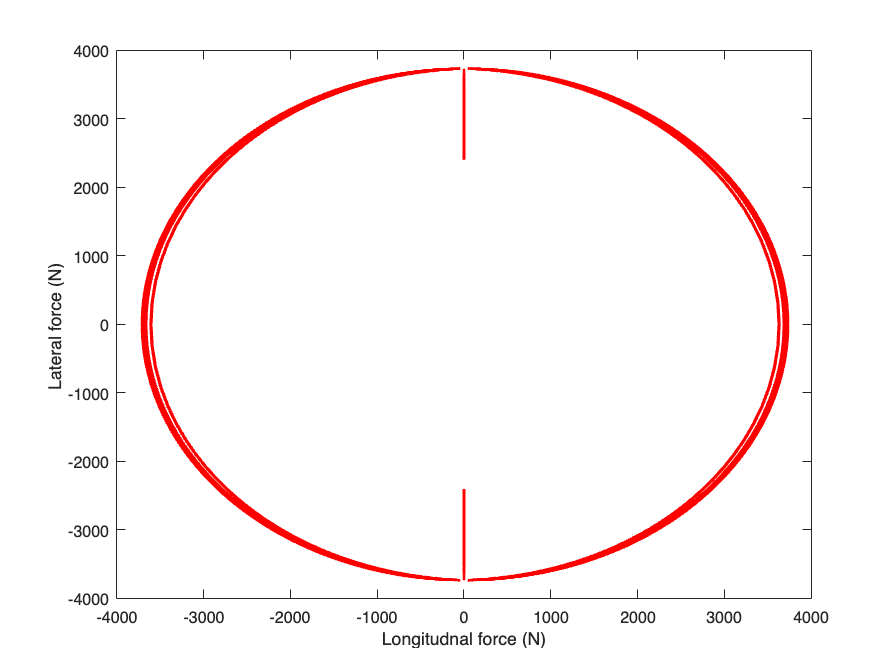

close all
figure
alpha = [-1000:1:1000]*pi/180;
for s = [-0.1 -0.2 -0.3 -0.4 -0.5 -0.6 -0.7 0 0.1 0.2 0.3 0.4 0.5 0.6 0.7]
    sim('Duggoff_Tire_Model');
    plot (Fx, Fy,'r','linewidth',2)
    hold on
    xlabel('Longitudnal force (N)');
    ylabel( 'Lateral force (N) ')
end

# Methods Functions

function [M,eta_t,lambda_t,lambda_f,I_w,R_w,Meq,C_d,rho,A_f,g,C_rr,C_x,L,l_f,l_r,C_y,I_z,mu,Fzf,Fzr] = getTireParameters()
    %Parameters
    warning off
    M=2000*9.81; % Mass of the vehicle[N]
    eta_t=0.9; %Transmission Efficiency	
    lambda_t=1.0; %Gear Ratio	
    lambda_f=4.1; %Final Drive Ratio	
    I_w=1; %Inertia of the Wheel[kgm2]
    R_w=0.3; %Wheel Radius[m]
    Meq=0.1*M; %Equivalent Mass Factor	
    C_d=0.29; %Drag coefficient 	
    rho=1.225; %Air density[kg/m3]
    A_f=2.8;%Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.015;%Rolling resistance coefficient	
    C_x=3e5; %Longitudinal Stiffness[N]
    L=2.85;%Wheelbase[m]
    l_f=1.3;%Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;%Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_y=1.5e5;%Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;%Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
    Fzf=(l_r*M)/(2*L);% Vertical force for front tire
    Fzr=(l_f*M)/(2*L);% Vertical force for rear tire
end 